clc; clear; close all;

% Cargar datos
filename = 'Five_times_Kinematics_HT_Query_MATLAB.xlsx';
data = xlsread(filename);
X = data

X =    34.0000         0    7.0000    4.9000   14.0000   21.4000    6.5000  -11.1000   -7.9000   -9.5000  -10.8000   -6.0000    6.4000   13.5000   11.4000   13.2000   37.4000   -2.9000   -2.1000   -2.2000   -3.9000   -7.7000    5.8000    7.2000    5.8000    6.1000    9.8000   40.6000   33.4000   20.8000    9.6000   10.4000   -1.0000    6.9000    6.6000    6.9000   -1.1000  -11.4000  -12.4000  -16.9000  -21.7000  -18.4000   18.6000   19.0000   18.0000   17.1000   16.2000   -0.3000    3.3000    0.2000
   30.0000         0    6.1000    3.9000   12.0000   18.2000   -6.2000  -18.3000  -14.4000  -16.4000  -17.9000  -13.4000         0    5.2000    2.2000    3.1000   31.2000    0.7000    2.1000    2.8000    1.0000    9.5000  -16.7000  -16.0000  -16.5000  -15.8000  -12.3000   30.9000   16.4000    6.7000   -3.8000   -0.5000    1.6000    7.7000    4.1000    4.2000   -5.4000   12.2000   12.8000    9.7000    9.0000   10.2000   10.1000    7.7000    9.9000   10.8000    9.3000    0.2000    2.4000   -0

[n, p] = size(X);

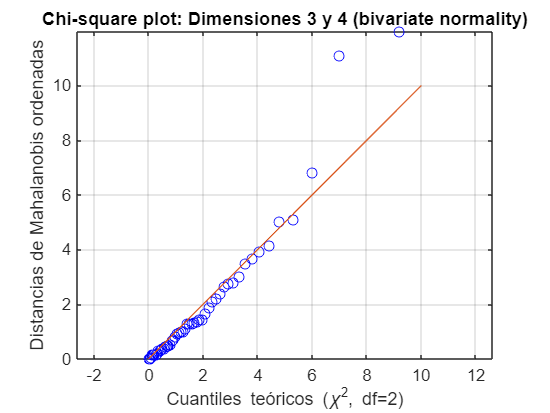

% Seleccionar dim 3 y 4
X_sub = X(:, [3 4]);  % n x 2

% Calcular vector de medias y matriz de covarianza
mean_vec = mean(X_sub);          % 1 x 2
cov_mat = cov(X_sub);            % 2 x 2
inv_cov = inv(cov_mat);

% Calcular distancias de Mahalanobis
mahal_dist = zeros(n, 1);
for i = 1:n
    diff = X_sub(i, :) - mean_vec;
    mahal_dist(i) = diff * inv_cov * diff';
end

% Cuantiles teóricos de chi-cuadrado con 2 grados de libertad
chi2_q = chi2inv(((1:n)' - 0.5) / n, 2);  % para bivariado, df = 2

% Graficar Chi-square plot
figure;
plot(chi2_q, sort(mahal_dist), 'bo');
hold on;
refline(1, 0);  % línea identidad
xlabel('Cuantiles teóricos (\chi^2, df=2)');
ylabel('Distancias de Mahalanobis ordenadas');
title('Chi-square plot: Dimensiones 3 y 4 (bivariate normality)');
axis equal;
grid on;

% Calcular vector de medias y matriz de covarianza
X = data(:,3:end)

X =     7.0000    4.9000   14.0000   21.4000    6.5000  -11.1000   -7.9000   -9.5000  -10.8000   -6.0000    6.4000   13.5000   11.4000   13.2000   37.4000   -2.9000   -2.1000   -2.2000   -3.9000   -7.7000    5.8000    7.2000    5.8000    6.1000    9.8000   40.6000   33.4000   20.8000    9.6000   10.4000   -1.0000    6.9000    6.6000    6.9000   -1.1000  -11.4000  -12.4000  -16.9000  -21.7000  -18.4000   18.6000   19.0000   18.0000   17.1000   16.2000   -0.3000    3.3000    0.2000   -0.2000   -4.4000
    6.1000    3.9000   12.0000   18.2000   -6.2000  -18.3000  -14.4000  -16.4000  -17.9000  -13.4000         0    5.2000    2.2000    3.1000   31.2000    0.7000    2.1000    2.8000    1.0000    9.5000  -16.7000  -16.0000  -16.5000  -15.8000  -12.3000   30.9000   16.4000    6.7000   -3.8000   -0.5000    1.6000    7.7000    4.1000    4.2000   -5.4000   12.2000   12.8000    9.7000    9.0000   10.2000   10.1000    7.7000    9.9000   10.8000    9.3000    0.2000    2.4000   -0.3000   -0.5000   -4

mu = mean(X);             % 1 x p
S = cov(X);               % p x p
invS = inv(S);

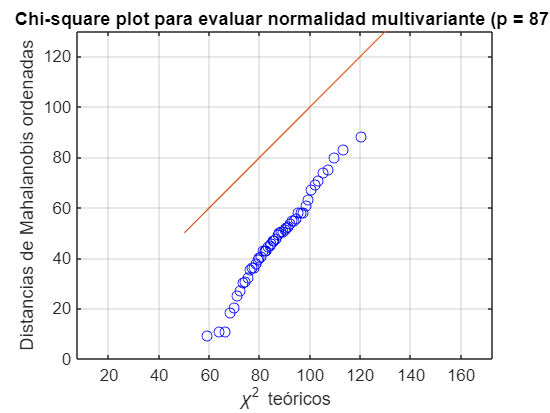


% Calcular distancias de Mahalanobis
D2 = zeros(n, 1);
for i = 1:n
    diff = X(i, :) - mu;
    D2(i) = diff * invS * diff';
end

% Cuantiles teóricos de chi-cuadrado con p grados de libertad
chi2_quant = chi2inv(((1:n)' - 0.5) / n, p);
D2_sorted = sort(D2);

% Graficar el Chi-square plot
figure;
plot(chi2_quant, D2_sorted, 'bo');
hold on;
refline(1, 0);  % línea identidad
xlabel('\chi^2 teóricos');
ylabel('Distancias de Mahalanobis ordenadas');
title(['Chi-square plot para evaluar normalidad multivariante (p = ', num2str(p), ')']);
axis equal;
grid on;